# ISONE hourly bid and demand data analysis

## Import selected datetime and price

load("../model_output/mat_files/selDateTimePriceISONE.mat");
selDateTimes = selDateTimePrice.DateTime;
selDates = selDateTimePrice.Date;
selHours = selDateTimePrice.Hour;
numSelDateTimes = size(selDateTimes, 1);
dt = 100;
selDate = selDates(dt)

selDate = datetime
   01/07/2019


selHour = selHours(dt)

selHour =      9


selDateStr = datestr(selDate, "mmm dd, yyyy");

## Import ISONE hourly bid data

% Import ISONE hourly bid data in 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
bidFileDir = "..\data\2019_DAM_BID_ISONE\";
bidFileName = "hbdayaheadenergyoffer_";
bidFileDate = datestr(selDate, 'yyyymmdd');
% bidDataStore = fileDatastore(bidFileDir + bidFileName, "ReadFcn", @importBidISONE, "UniformRead", true);
% bidAll = readall(bidDataStore);
hourlyBid = importBidISONE(bidFileDir + bidFileName + bidFileDate + ".csv");

## Import ISONE hourly demand data

% Import ISONE hourly demand data in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);
clear demandDataStore;

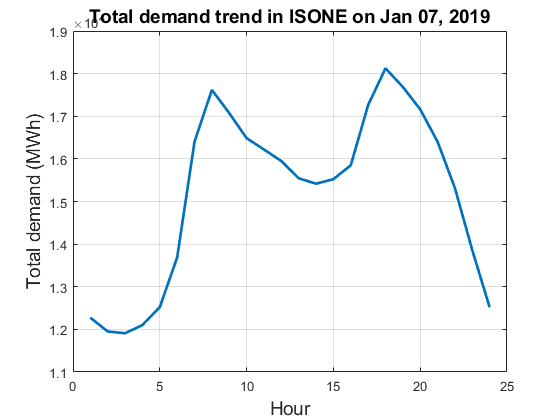

hourlyDemand = demandAll(demandAll.Date == selDate, :);
figure;
plot(hourlyDemand.DayAheadDemand, "LineWidth",2);
txt = sprintf("Total demand trend in ISONE on %s", selDateStr);
title(txt, "FontSize", 14);
xlabel("Hour", "FontSize", 14);
ylabel("Total demand (MWh)", "FontSize", 14);
box on; grid on;
saveas(gcf, "../model_output/figures/dailyDemandTrend.png");

## Calculate aggregated supply function

### Construct stepwise aggregated supply function

% Obtain total demand at the selected hour
selHourDemand = hourlyDemand(hourlyDemand.Hour == selHour, :).DayAheadDemand;
% Obtain bids at the selected hour
allBids = hourlyBid(hourlyBid.Hour == selHour, :);
allBids = removevars(allBids, ["Date", "Hour", "MustTakeEnergy", "MaximumDailyEnergyAvailable", "EconomicMaximum", "EconomicMinimum", ...
    "ColdStartupPrice", "IntermediateStartupPrice", "HotStartupPrice", "NoLoadPrice"]);
allBids = movevars(allBids, "UnitStatus", "After", "AssetID");
allBids = movevars(allBids, "DateTime", "Before", "ParticipantID");
% remove unavailable units, left with economic and must-run units
availBids = allBids(allBids.UnitStatus ~= "UNAVAILABLE", :);

% Stack all bids together 
seg1 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment1Price", "Segment1MW"]));
seg2 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment2Price", "Segment2MW"]));
seg3 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment3Price", "Segment3MW"]));
seg4 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment4Price", "Segment4MW"]));
seg5 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment5Price", "Segment5MW"]));
seg6 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment6Price", "Segment6MW"]));
seg7 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment7Price", "Segment7MW"]));
seg8 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment8Price", "Segment8MW"]));
seg9 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment9Price", "Segment9MW"]));
seg10 = table2cell(availBids(:, ["ParticipantID", "AssetID", "Segment10Price", "Segment10MW"]));
stackedBids = cell2table([seg1; seg2; seg3; seg4; seg5; seg6; seg7; seg8; seg9; seg10], ...
    "VariableNames", ["ParticipantID", "AssetID", "SegmentPrice", "SegmentMW"]);
% Remove NA bids
stackedBids = rmmissing(stackedBids);
% Sort bids by price from lowest to highest
stackedBids = sortrows(stackedBids, "SegmentPrice", "ascend");
% Calculate cumulative bid quantity
stackedBids.CumsumMW = cumsum(stackedBids.SegmentMW)

stackedBids = 770×5 table
    ParticipantID    AssetID    SegmentPrice    SegmentMW    CumsumMW
    _____________    _______    ____________    _________    ________

       124454         57942         -150           0.1          0.1  
       384652         55290         -150             6          6.1  
       399648         42103         -150             8         14.1  
       399648         46072         -150             3         17.1  
       399648         77213         -150            13         30.1  
       399648         87105         -150            32         62.1  
       399648         97130         -150            30         92.1  
       412080         15908         -150            15        107.1  
       475203         52500         -150             2        109.1  
       547098         63551      

### Gaussian kernel smoothed aggregated supply function

segBids = [stackedBids.SegmentMW, stackedBids.SegmentPrice];
smoothedBids = gaussianCurve(segBids, min(segBids(:, 2)), max(segBids(:, 2)), 1);

### Plot aggregated supply function

stepBids = [stackedBids.CumsumMW, stackedBids.SegmentPrice];
stepNum = size(stepBids, 1);
stepBids4Plot = zeros(stepNum*2, 2);
for i = 1:stepNum-1
    stepBids4Plot(2*i, :) = stepBids(i, :);
    stepBids4Plot(2*i+1, 1) = stepBids(i, 1);
    stepBids4Plot(2*i+1, 2) = stepBids(i+1, 2);
end
stepBids4Plot(1, 2) = stepBids(1, 2);
stepBids4Plot(end, :) = stepBids(end, :);
aggSupplyCurve = stepBids4Plot;
aggSupplyCurveSmoothed = smoothedBids;

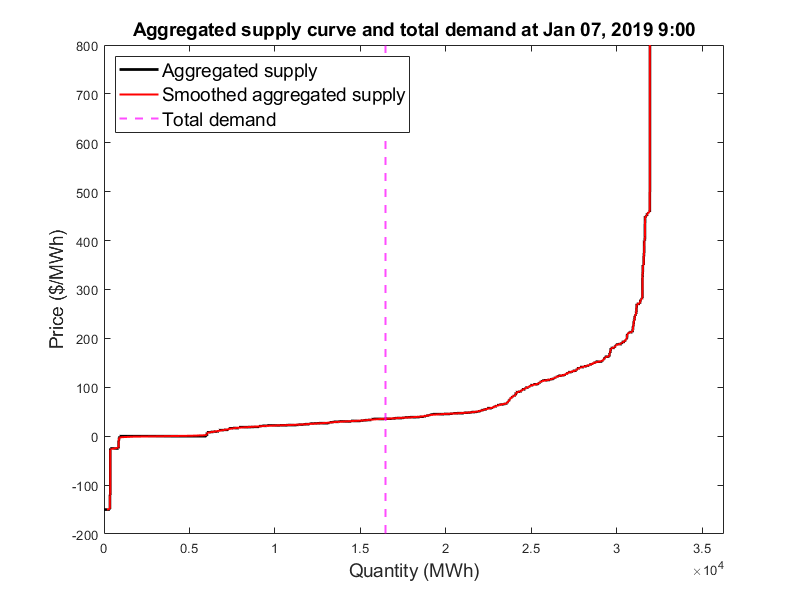

figure;
hold on;
plot(aggSupplyCurve(:, 1), aggSupplyCurve(:, 2), 'k', "LineWidth",2);
plot(aggSupplyCurveSmoothed(:, 1), aggSupplyCurveSmoothed(:, 2), 'r', "LineWidth",1.5);
xline(selHourDemand, 'm--', "LineWidth",1.5);
hold off; box on;
legend(["Aggregated supply", "Smoothed aggregated supply", "Total demand"], "Location", "northwest", "FontSize", 14);
txt = sprintf("Aggregated supply curve and total demand at %s %d:00", selDateStr, selHour);
title(txt, "FontSize", 14);
xlabel("Quantity (MWh)", "FontSize", 14);
ylabel("Price ($/MWh)", "FontSize", 14);
xlim([0, selHourDemand*2.2]);
ylim([-200, 800]);
set(gcf, "Position", [50, 50, 800, 600]);
saveas(gcf, "../model_output/figures/aggSupply.png");

## Calculate supply curve of top market participants

### Find out awarded bids

stackedBids.AwardStatus = stackedBids.CumsumMW <= selHourDemand;
stackedBids.AwardStatus = categorical(stackedBids.AwardStatus);
stackedBids.AwardedMW = zeros(size(stackedBids, 1),1);
foundMarginal = 0;
for i=1:size(stackedBids, 1)
    if (stackedBids(i, :).AwardStatus == "true") && (foundMarginal == 0)
        stackedBids(i, :).AwardedMW = stackedBids(i, :).SegmentMW;
    elseif (stackedBids(i, :).AwardStatus == "false") && (foundMarginal == 0)
        foundMarginal = 1;
        stackedBids(i, :).AwardStatus = "marginal";
        stackedBids(i, :).AwardedMW = selHourDemand - stackedBids(i-1, :).CumsumMW;
        clearingPrice = stackedBids(i, :).SegmentPrice;
    elseif (stackedBids(i, :).AwardStatus == "false") && (foundMarginal == 1)
        stackedBids(i, :).AwardedMW = 0;
    else
        stackedBids(i, :).AwardedMW = nan;
    end
end
stackedBids.AwardedCumsumMW = cumsum(stackedBids.AwardedMW)

stackedBids = 770×8 table
    ParticipantID    AssetID    SegmentPrice    SegmentMW    CumsumMW    AwardStatus    AwardedMW    AwardedCumsumMW
    _____________    _______    ____________    _________    ________    ___________    _________    _______________

       124454         57942         -150           0.1          0.1         true           0.1              0.1     
       384652         55290         -150             6          6.1         true             6              6.1     
       399648         42103         -150             8         14.1         true             8             14.1     
       399648         46072         -150             3         17.1         true             3             17.1     

### Calculate total awarded bids of each market participant

participantIDs = unique(availBids.ParticipantID);
partAwarded = zeros(size(participantIDs, 1), 1);
partUnawarded = zeros(size(participantIDs, 1), 1);
partTotBid = zeros(size(participantIDs, 1), 1);
for i = 1:size(participantIDs, 1)
    partBids = stackedBids(stackedBids.ParticipantID == participantIDs(i), :);
    partAwarded(i) = sum(partBids.AwardedMW);
    partTotBid(i) = sum(partBids.SegmentMW);
    partUnawarded(i) = partTotBid(i) - partAwarded(i);
end
% find out the market participants with largest awarded bid amount
partBidTable = table(participantIDs, partAwarded, partUnawarded, partTotBid);
partBidTable = sortrows(partBidTable, "partAwarded", "descend")

partBidTable = 72×4 table
    participantIDs    partAwarded    partUnawarded    partTotBid
    ______________    ___________    _____________    __________

        591975            2548             858            3406  
        401592            2129               0            2129  
        212494            1784             365            2149  
        902793          1506.2          1327.6          2833.8  
        504170          1436.7          1031.7          2468.4  
        206845            1275          1302.9          2577.9  
        749668             761              61             822  
        872788             698             296             994  
        219842             680               0             680  
        595644             615               0             615  
        295534             431             191           

topParticipants = partBidTable(1:10, :).participantIDs;
topPartAwarded = partBidTable(1:10, :).partAwarded;

### Construct supply function of top market participants

topPartBidsTables = cell(size(topParticipants));
smoothedSupplyCurves = cell(size(topParticipants));
for i = 1:size(topParticipants, 1)
    % Obtain bids off one top participant
    partBids = availBids(availBids.ParticipantID == topParticipants(i), :);
    % Stack all bids together 
    seg1 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment1Price", "Segment1MW"]));
    seg2 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment2Price", "Segment2MW"]));
    seg3 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment3Price", "Segment3MW"]));
    seg4 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment4Price", "Segment4MW"]));
    seg5 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment5Price", "Segment5MW"]));
    seg6 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment6Price", "Segment6MW"]));
    seg7 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment7Price", "Segment7MW"]));
    seg8 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment8Price", "Segment8MW"]));
    seg9 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment9Price", "Segment9MW"]));
    seg10 = table2cell(partBids(:, ["ParticipantID", "AssetID", "Segment10Price", "Segment10MW"]));
    partStackedBids = cell2table([seg1; seg2; seg3; seg4; seg5; seg6; seg7; seg8; seg9; seg10], ...
        "VariableNames", ["ParticipantID", "AssetID", "SegmentPrice", "SegmentMW"]);
    % Remove NA bids
    partStackedBids = rmmissing(partStackedBids);
    % Sort bids by price from lowest to highest
    partStackedBids = sortrows(partStackedBids, "SegmentPrice", "ascend");
    % Calculate cumulative bid quantity
    partStackedBids.CumsumMW = cumsum(partStackedBids.SegmentMW);
    topPartBidsTables{i} = partStackedBids;
    % Calculate smoothed bid curve
    segBids = [partStackedBids.SegmentMW, partStackedBids.SegmentPrice];
    smoothedBids = gaussianCurve(segBids, min(segBids(:, 2)), max(segBids(:, 2)), 1);
    smoothedSupplyCurves{i} = smoothedBids;    
end

### Plot supply curve of top market participants

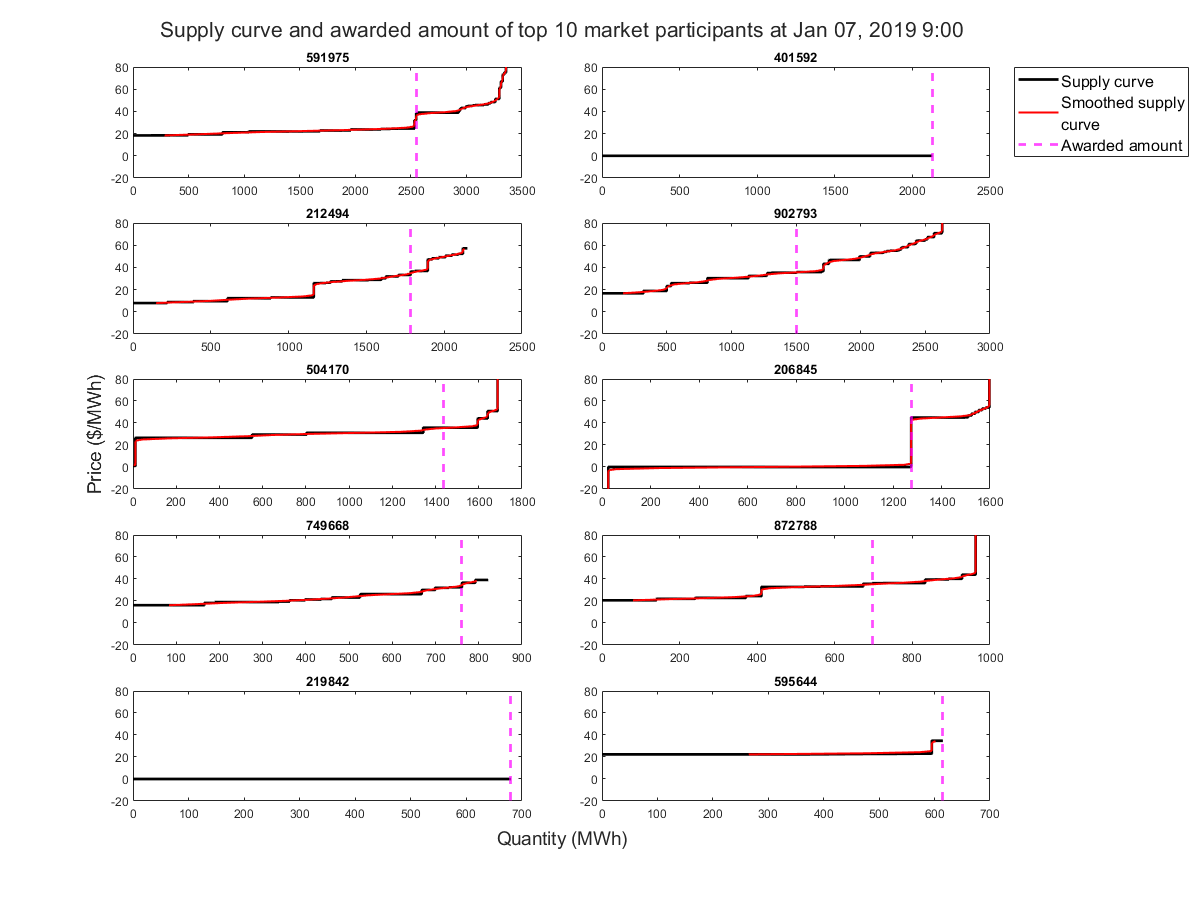

partSupplyCurves = cell(size(topParticipants));
t = tiledlayout(5,2,"TileSpacing","compact");
for i = 1:size(topParticipants, 1)
    % Construct step fuction for plot
    partStackedBids = topPartBidsTables{i};
    partiID = topParticipants(i);
    stepBids = [partStackedBids.CumsumMW, partStackedBids.SegmentPrice];
    stepNum = size(stepBids, 1);
    stepBids4Plot = zeros(stepNum*2, 2);
    for j = 1:stepNum-1
        stepBids4Plot(2*j, :) = stepBids(j, :);
        stepBids4Plot(2*j+1, 1) = stepBids(j, 1);
        stepBids4Plot(2*j+1, 2) = stepBids(j+1, 2);
    end
    stepBids4Plot(1, 2) = stepBids(1, 2);
    stepBids4Plot(end, :) = stepBids(end, :);
    partSupplyCurves{i} = stepBids4Plot;
    
    % Plot supply function
    nexttile;
    hold on;
    plot(partSupplyCurves{i}(:, 1), partSupplyCurves{i}(:, 2), 'k', "LineWidth",2);
    % Plot smoothed supply curve
    plot(smoothedSupplyCurves{i}(:, 1), smoothedSupplyCurves{i}(:, 2), 'r', "LineWidth",1.5);
    % Plot awarded supply amount
    xline(topPartAwarded(i), 'm--',"LineWidth",2);    
    hold off; box on;
    if i==2
        legend(["Supply curve", "Smoothed supply\newlinecurve", "Awarded amount"], "Location", "bestoutside", "FontSize",12);
    end    
    title(partiID);
    ylim([-20 80]);
end
xlabel(t, "Quantity (MWh)", "FontSize", 14);
ylabel(t, "Price ($/MWh)", "FontSize", 14);
txt = sprintf("Supply curve and awarded amount of top 10 market participants at %s %d:00", selDateStr, selHour);
title(t, txt, "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/partSupplyCurves.png");

## Plot aggregated supply curve excluding one top market participant

### Construct aggregated supply of other market participants

topOtherBidsTables = cell(size(topParticipants));
otherTotAwarded = zeros(size(topParticipants));
smoothedOtherSupplyCurves = cell(size(topParticipants));
for i = 1:size(topParticipants, 1)
    otherBids = stackedBids(stackedBids.ParticipantID ~= topParticipants(i), :);
    otherBids.otherCumsumMW = cumsum(otherBids.SegmentMW);
    otherTotAwarded(i) = sum(otherBids.AwardedMW);
    topOtherBidsTables{i} = otherBids;
    % Calculate smoothed bid curve
    segBids = [otherBids.SegmentMW, otherBids.SegmentPrice];
    smoothedBids = gaussianCurve(segBids, min(segBids(:, 2)), max(segBids(:, 2)), 1);
    smoothedOtherSupplyCurves{i} = smoothedBids;
end

### Plot aggregated supply of other market participants

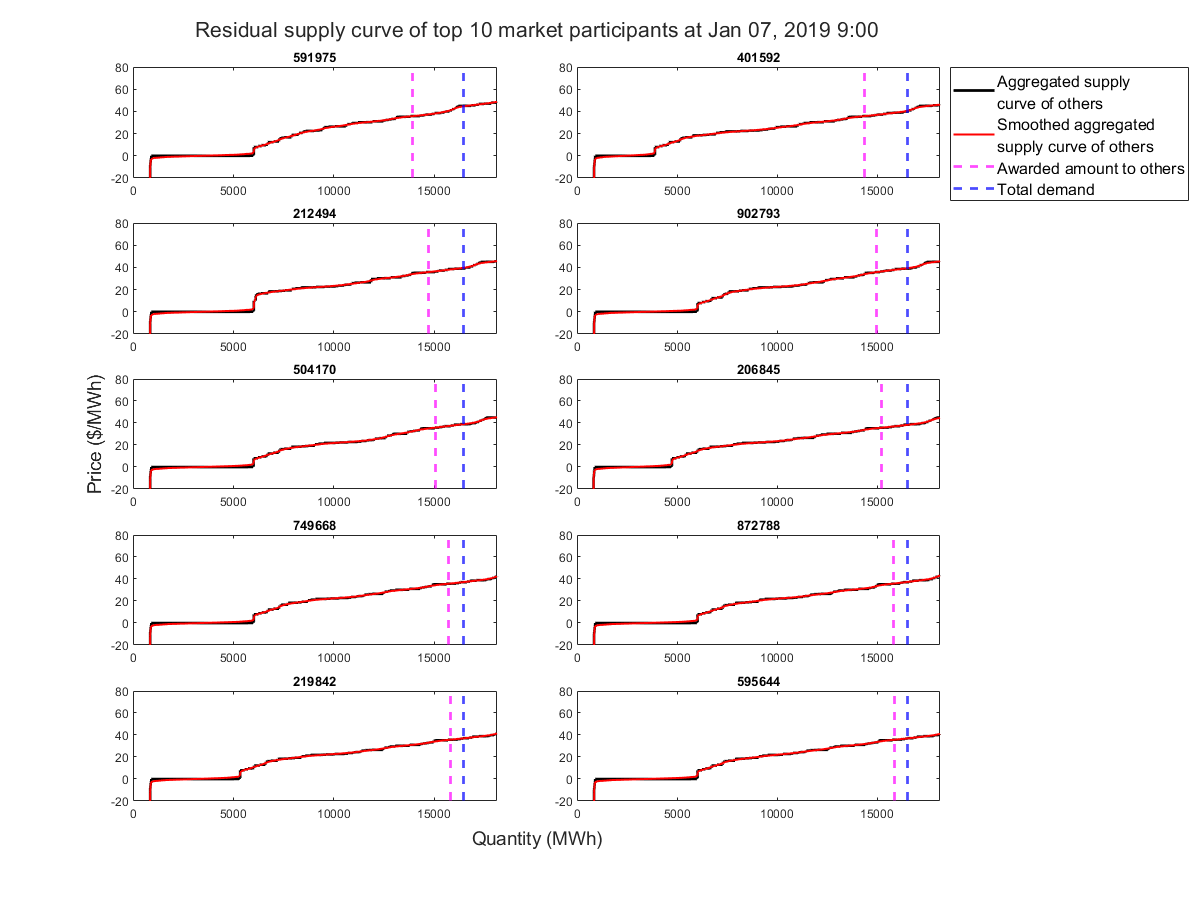

otherSupplyCurves = cell(size(topParticipants, 1), 1);
t = tiledlayout(5,2,"TileSpacing","compact");
for i = 1:size(topParticipants, 1)
    % Construct step fuction for plot
    otherStackedBids = topOtherBidsTables{i};
    partiID = topParticipants(i);
    stepBids = [otherStackedBids.otherCumsumMW, otherStackedBids.SegmentPrice];
    stepNum = size(stepBids, 1);
    stepBids4Plot = zeros(stepNum*2, 2);
    for j = 1:stepNum-1
        stepBids4Plot(2*j, :) = stepBids(j, :);
        stepBids4Plot(2*j+1, 1) = stepBids(j, 1);
        stepBids4Plot(2*j+1, 2) = stepBids(j+1, 2);
    end
    stepBids4Plot(1, 2) = stepBids(1, 2);
    stepBids4Plot(end, :) = stepBids(end, :);
    otherSupplyCurves{i} = stepBids4Plot;
    
    % Plot supply function exclude one top participant
    nexttile;
    hold on;
    plot(otherSupplyCurves{i}(:, 1), otherSupplyCurves{i}(:, 2), 'k', "LineWidth",2);
    % Plot smoothed supply curve of other participants
    plot(smoothedOtherSupplyCurves{i}(:, 1), smoothedOtherSupplyCurves{i}(:, 2), 'r', "LineWidth",1.5);
    % Plot total awarded amount of others and total demand
    xline(otherTotAwarded(i), 'm--', "LineWidth",2);
    xline(selHourDemand, 'b--', "LineWidth",2);
    hold off; box on;
    if i==2
        legend(["Aggregated supply\newlinecurve of others", "Smoothed aggregated\newlinesupply curve of others", "Awarded amount to others", "Total demand"], ...
            "Location", "bestoutside", "FontSize", 12);
    end    
    title(partiID);
    axis([0 selHourDemand*1.1 -20 80]);
end
xlabel(t, "Quantity (MWh)", "FontSize", 14);
ylabel(t, "Price ($/MWh)", "FontSize", 14);
txt = sprintf("Residual supply curve of top 10 market participants at %s %d:00", selDateStr, selHour);
title(t, txt, "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/partSupplyOthers.png");

## Calculate and plot residuel demand function of top market participants

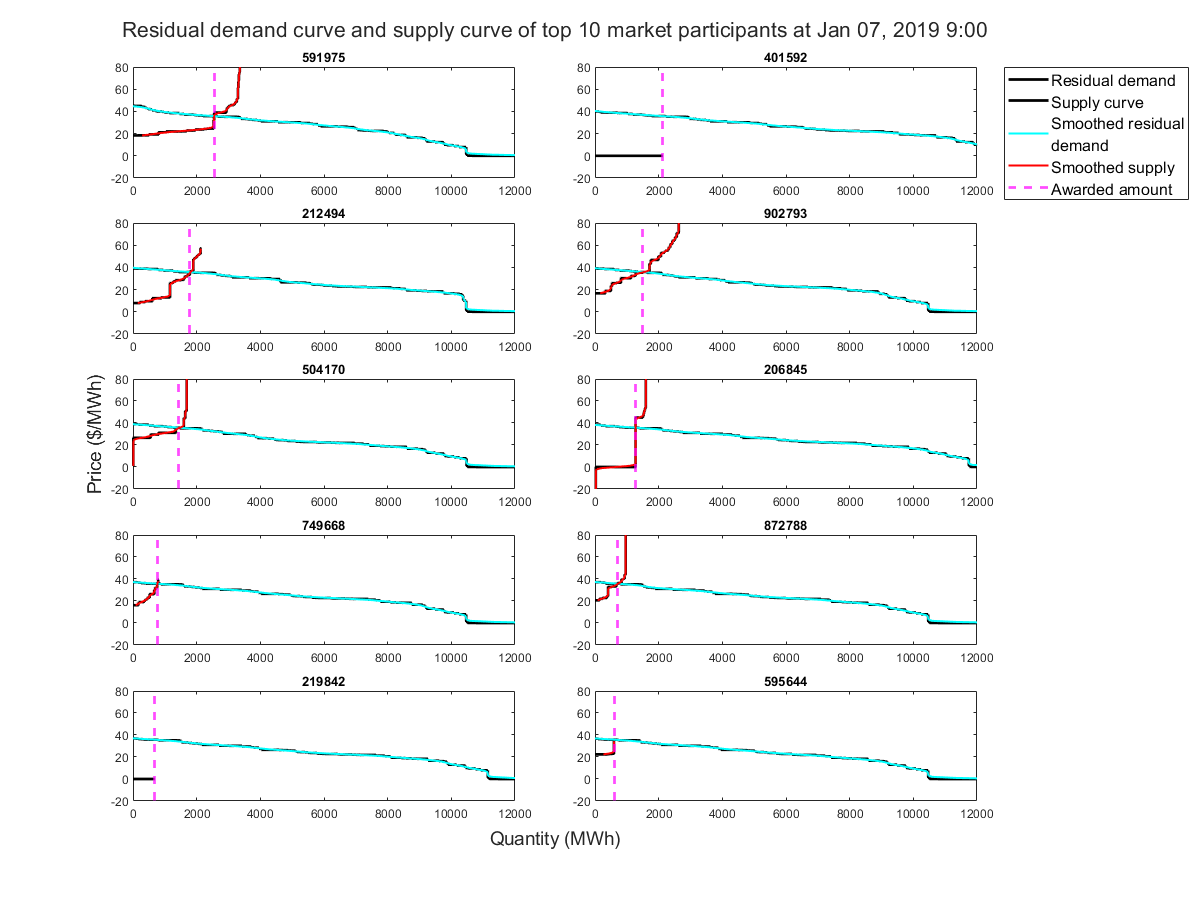

resiDemandCurves = cell(size(topParticipants));
smoothedResiDemandCurves = cell(size(topParticipants));
t = tiledlayout(5,2,"TileSpacing","compact");
for i = 1:size(topParticipants, 1)
    partiID = topParticipants(i);
    % Construct step fuction for residual demand
    otherSupplyCurve = otherSupplyCurves{i};
    flipedSupplyCurve = flipud(otherSupplyCurve);
    resiDemandCurve = flipedSupplyCurve;
    resiDemandCurve(:, 1) = selHourDemand - flipedSupplyCurve(:, 1);
    resiDemandCurves{i} = resiDemandCurve;
    
    % Construct smoothed residual demand curve
    smoothedOtherSupplyCurve = smoothedOtherSupplyCurves{i};
    flippedSmoothedOtherSupplyCurve = flipud(smoothedOtherSupplyCurve);
    smoothedResiDemandCurve = flippedSmoothedOtherSupplyCurve;
    smoothedResiDemandCurve(:, 1) = selHourDemand - flippedSmoothedOtherSupplyCurve(:, 1);
    smoothedResiDemandCurves{i} = smoothedResiDemandCurve;
    
    % Plot residual demand
    nexttile;
    hold on;
    plot(resiDemandCurves{i}(:, 1), resiDemandCurves{i}(:, 2), 'k', "LineWidth",2);    
    % Plot supply curve
    plot(partSupplyCurves{i}(:, 1), partSupplyCurves{i}(:, 2), 'k', "LineWidth",2);
    % Plot smoothed residual demand
    plot(smoothedResiDemandCurves{i}(:, 1), smoothedResiDemandCurves{i}(:, 2), 'c', "LineWidth",1.5);  
    % Plot smoothed supply curve
    plot(smoothedSupplyCurves{i}(:, 1), smoothedSupplyCurves{i}(:, 2), 'r', "LineWidth",1.5);
    % Plot awarded amount
    xline(topPartAwarded(i), 'm--', "LineWidth",2);    
    hold off; box on;
    if i==2
        legend(["Residual demand", "Supply curve", "Smoothed residual\newlinedemand", "Smoothed supply", "Awarded amount"], "Location", "bestoutside", "FontSize", 12);
    end    
    title(partiID);
    axis([0 12000 -20 80]);
end
xlabel(t, "Quantity (MWh)", "FontSize", 14);
ylabel(t, "Price ($/MWh)", "FontSize", 14);
txt = sprintf("Residual demand curve and supply curve of top 10 market participants at %s %d:00", selDateStr, selHour);
title(t, txt, "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/partRDSupply.png");

## Calculate marginal cost of top market participants

topMarginalCosts1 = zeros(size(topParticipants));
topMarginalCosts2 = zeros(size(topParticipants));
marketClearingPrice = selDateTimePrice(dt, :).averageLMP

marketClearingPrice =         29.08


clearingPrice

clearingPrice =         35.76


% Calculate using clearing price from simple economic dispatch
for i = 1:size(topParticipants, 1)
    otherStackedBids = topOtherBidsTables{i};
    segBids = [otherStackedBids.SegmentMW, otherStackedBids.SegmentPrice];
    supplyGradient = gaussianGradient(segBids, clearingPrice, 1);
    resiDemandGradient = - supplyGradient;
    topMarginalCosts1(i) = clearingPrice + topPartAwarded(i)/resiDemandGradient;
end
% Calculate using market clearing price from ISONE
for i = 1:size(topParticipants, 1)
    otherStackedBids = topOtherBidsTables{i};
    segBids = [otherStackedBids.SegmentMW, otherStackedBids.SegmentPrice];
    supplyGradient = gaussianGradient(segBids, marketClearingPrice, 1);
    resiDemandGradient = - supplyGradient;
    topMarginalCosts2(i) = marketClearingPrice + topPartAwarded(i)/resiDemandGradient;
end
topQuantityMC = table(topParticipants, topPartAwarded, topMarginalCosts1, topMarginalCosts2)

topQuantityMC = 10×4 table
    topParticipants    topPartAwarded    topMarginalCosts1    topMarginalCosts2
    _______________    ______________    _________________    _________________

        591975               2548             31.325               22.545      
        401592               2129             32.063                23.62      
        212494               1784             32.484               22.872      
        902793             1506.2             32.167               24.491      
        504170             1436.7             32.738               23.572      
        206845               1275             33.546                25.81      
        749668                761             34.418               27.082      
        872788                698             34.409                27.29      
        219842                680   